### Write a MATLAB program to implement Newton’s method. Using this find the root of the equation 				

### x = 1 + 0.3 cos(x) with an error tolerance of ε = 10−6. 

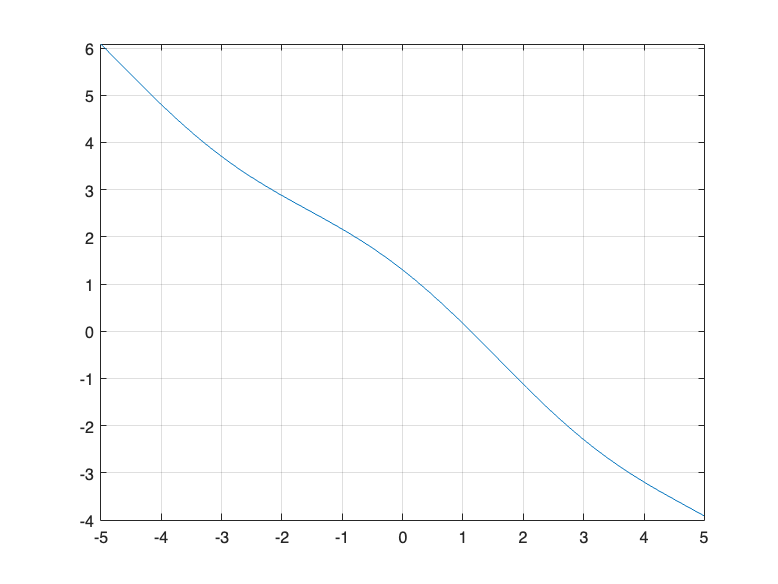

% 1 + 0.3 cos(x)

x = 0;
Tol = 1e-6;
iter = 1;
dx=1;   %this is temp
f=1.3;  

fplot(@(x) (1 -x + 0.3*cos(x)))
grid ON;


fprintf('iteration      x           dx           f(x)\n')

iteration      x           dx           f(x)


fprintf('%3i       %12.8f %12.8f %12.8f\n',iter,x,dx,f)

  1         0.00000000   1.00000000   1.30000000



while (dx>Tol)  
    iter = iter + 1;
    fdash = -1 -0.3*sin(x);
    xnew = x - (f/fdash);   
    dx=abs(x-xnew);     
    x = xnew;
    f = 1 - x + 0.3*cos(x);   
    fprintf('%3i       %12.8f %12.8f %12.8f\n',iter,x,dx,f)
end

  2         1.30000000   1.30000000  -0.21975035
  3         1.12952766   0.17047234  -0.00140157
  4         1.12842515   0.00110250  -0.00000008
  5         1.12842509   0.00000006  -0.00000000



answ= x

answ =    1.128425092992225
